%{
--Code for calculating the decay of an exited two level system into a bath
of other two level systems. The setup is similar to Wigner-Weisskopf theory
of spontaneous emission. However, here the couplings can also be set
symmetrically such that every TLS is coupled to all other TLSs in the
bath [1]. The aim of the code is to compare the two cases and serve as a
test bed for the corresponding analytical results.--
----------------------------------------------------------------------------
For the basic user of the code the important variables are:
----------------------------------------------------------------------------
(1) N - this is the total number of two levels in the bath. Note that the
intially exited site is not considered to be part of the bath and therefore
N+1 is overall number of TLSs.

(2) Nr - number of iterations to average over

(3) gamma - sets the magnitude of the couplings

(4) include_mutual - 0 to generate no mutual couplings in the bath and 1 if
otherwise
----------------------------------------------------------------------------
[1] J.P. Pekola, B. Karimi, M. Cattaneo, and S. Maniscalco, "Long-time relax-
ation of a finite spin bath linearly coupled to a qubit,” Open Systems amp;
Information Dynamics, vol. 30, June 2023.
%}

%--Defining the variables of the problem--%
close all

N = 100; 
Nr = 25; 
w = 1;  %The qubit frequency (taken to be normalized to 1)
include_mutual = 1; 
gamma = w/(5*sqrt(2)); 

te_results = zeros(1, N); %The array for collecting the results of long time evolution
gge_results = zeros(1, N+1); %The array for collecting the results of the GGE prediction

dia1 = sort(2*w*rand(N,1));
for idx = 1:Nr
    
%{
%In this section we first generate the bath Hamiltonian H1
according to the rule Hij = [-gamma/sqrt(N),gamma/sqrt(N)] and Hii =
[0,2*Omega]. Then we expand it to include the initially exited site to form
the total Hamiltonian H.
%}
    
a = -(gamma/sqrt(N)) + 2*(gamma/sqrt(N))*rand(N); 
a = include_mutual*triu(a);
H1 = a+a';
H1 = H1 - diag(diag(H1)) + diag(dia1);

%Diagonalize the bath Hamiltonian
[vek1, ek1] = eig(H1);

%vek1 = [vek1; zeros(N+3,N)];
%vek2 = [zeros(N+3,N); vek2];
%vek = [vek1 vek2]

%Generate the couplings from the baths to the resonators 
lambda1 = -(gamma/sqrt(N)) + 2*(gamma/sqrt(N))*rand(N,1);

%Build the total Hamiltonian 
H = blkdiag(H1, w);
H(1:N,N+1) = lambda1;
H(N+1,1:N) = lambda1';

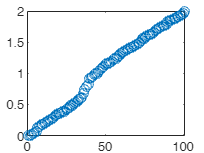

%{
In this section, we diagonalize the total Hamiltonian H and set the intial state.
%}

[vel, el] = eig(H); %Diagonalize the total Hamiltonian to eigenvectors vel and eigevalues el
plot(diag(el), 'o')
xi02 = zeros(N+1);
xi02(N+1, N+1) = 1; 
xi0 = xi02; %The initial state of the system 


%{
In this section, we time-evolve the intial density matrix and calculate the resulting populations.
%}
tmax = 8000000000; %The final time at which the populations are calculated
t = linspace(0,tmax,2); %Vector for times for which to calculate the time evolution
%E1 =  zeros(1, N);

for i = 1:length(t)
    Ul = expm(1i*t(i)*el); %Time-evolution operator exp(iHt) in the eigenbasis of H (easy to calculate)
    Uj = vel*Ul*(vel'); %Convert it to the basis of the sites
    xi = (Uj')*xi0*Uj; %\rho(t) = exp(-iHt)\rho(t=0)exp(iHt)
end

%{
for j = 1:N
     Opj = zeros(N+1);
     Opj(j,j) = 1; %Defining the number operator Opj of the j:th site
     E1(j) = trace(Opj*xi); %Calculating the expectation value of it
end
%}
e1 = diag(xi);
E1 = e1(1:N);

el = diag(el);

%{
In this section, we calculate the numerical GGE prediction for the populations, which is to compared
the long-time evolution. Basically, we just implement a convolution
formula.
%}
nau = zeros(1, N+1);
ujt = abs(vel(N+1,:)).^2;

for k = 1:(N+1)
    uki = abs(vel(k,:)).^2;
    nau(k) = dot(ujt, uki);
end

te_results = te_results+E1;
gge_results = gge_results+nau;


end

%{
Finally, we average over the set number of iterations.
%}
te_result = te_results/Nr;
gge_result = gge_results/Nr;
epsilon = sort(dia1);

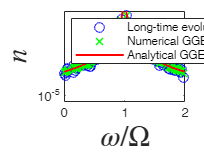

%{
In this section, we plot the results of both the numerical long-time
evolution and the GGE prediction and compare an analytical formula.
%}

omega = linspace(0,2*w,1000000); 
gavg = (gamma^2)/(3*N);
Omega = w;
nu0 = N/(2*Omega);
g2 = (gamma^2)/(3*N);
rate = pi*nu0*gavg;
nl = 2*gavg./((1-omega).^2+(2*rate)^2); %The analytical prediction for the populations

%-The final plotting of the results: 
% (i) Numerical long-time evolution (ii) Numerical GGE (iii) Analytical
% -%
a1 = semilogy(dia1, te_result, 'o', "Color", 'b');
hold on

a2 = plot(dia1, gge_result(1:N), 'x', "LineWidth", 1.1, "Color","g");
a3 = plot(omega, nl, "LineWidth", 1.2, "Color", "r");

xlabel("$\omega/\Omega$", 'Interpreter',"latex", 'FontSize',18)
ylabel("$n$", 'Interpreter',"latex", 'FontSize',18)
legend([a1(1), a2(1), a3(1)], 'Long-time evolution', 'Numerical GGE','Analytical GGE', 'location', "northwest")
ylim([0.5*10^(-5),10^(-1)])
hold off

%{
Uncomment the line below and change the path to your desired location to save the resulting data.
%}

%save("mutual_off", "te_result", "gge_result", "dia1")

